% 아래와 같은 분포를 갖는 독립적인 n개의 random variables의 합으로 
% 새로운 r.v.을 생성하여 central limit theorem 확인 (새로운 r.v.의 개수= 10^7)
% Uniform Distribution (0 ≤ x ≤ 1)
% (a) n = 3      (b) n = 6      (c) n = 12      (d) n = 20
% 0부터 1사이에서 uniform distribution을 갖는 n개의 r.v.들의 합으로 새로운 r.v.을 생성한다.

## n = 3

sgtitle('normpdf')
arr1 = zeros(1,10^7);
for cnt = 1:3
    for i = 1:10^7
        arr1(i) = arr1(i) + rand();
    end
end
m1 = mean(arr1)

m1 = 1.5002

% pdf함수기 때문에 arr1에 평균을 빼주고 정렬해줘야함
y = sort(arr1-m1)

y =    -1.4956   -1.4951   -1.4913   -1.4899   -1.4897   -1.4891   -1.4881   -1.4862   -1.4846   -1.4836   -1.4831   -1.4828   -1.4827   -1.4821   -1.4815   -1.4814   -1.4808   -1.4808   -1.4805   -1.4790   -1.4789   -1.4785   -1.4784   -1.4782   -1.4780   -1.4769   -1.4760   -1.4759   -1.4755   -1.4754   -1.4752   -1.4746   -1.4742   -1.4742   -1.4735   -1.4734   -1.4730   -1.4729   -1.4724   -1.4718   -1.4715   -1.4711   -1.4710   -1.4709   -1.4705   -1.4702   -1.4696   -1.4695   -1.4692   -1.4692


% y1의 원소는 arr1의 원소가 될 확률을 의미
y1 = normpdf(y,0,1)

y1 =     0.1304    0.1305    0.1312    0.1315    0.1315    0.1317    0.1318    0.1322    0.1325    0.1327    0.1328    0.1329    0.1329    0.1330    0.1331    0.1332    0.1333    0.1333    0.1333    0.1336    0.1336    0.1337    0.1338    0.1338    0.1338    0.1341    0.1342    0.1342    0.1343    0.1344    0.1344    0.1345    0.1346    0.1346    0.1347    0.1347    0.1348    0.1348    0.1349    0.1351    0.1351    0.1352    0.1352    0.1352    0.1353    0.1354    0.1355    0.1355    0.1356    0.1356


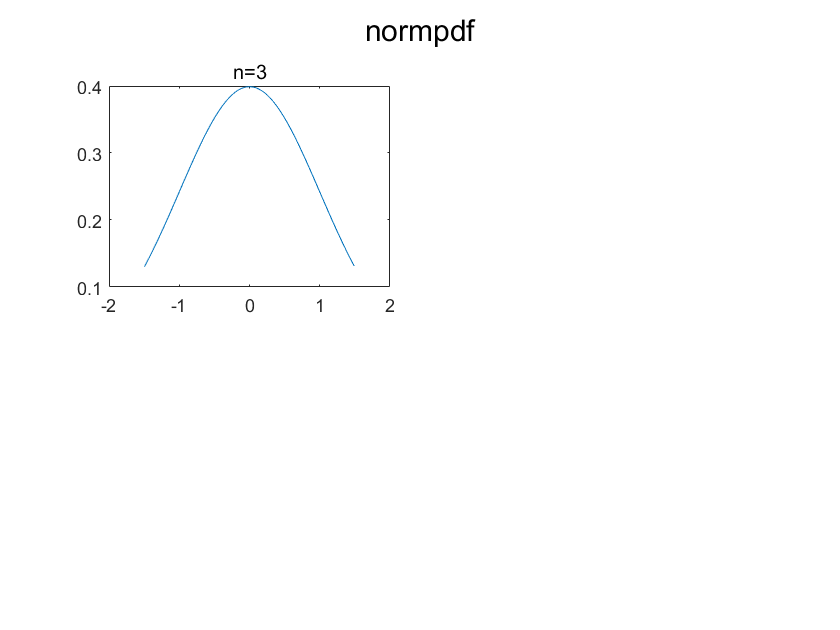

subplot(2,2,1)
plot(y,y1)
title('n=3')

% histogram(arr1) <- matlab doesn't recommand it


## n = 6

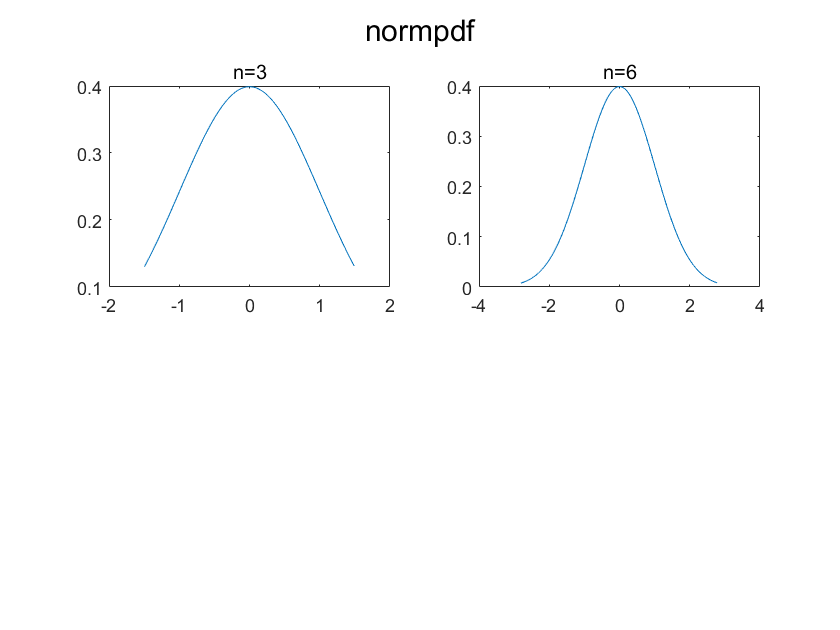

arr2 = zeros(1,10^7);
for cnt = 1:6
    for i = 1:10^7
        arr2(i) = arr2(i) + rand();
    end
end
m2 = mean(arr2);
y = sort(arr2-m2);
y2 = normpdf(y,0,1);
subplot(2,2,2)
plot(y,y2)
title('n=6')

## n = 12

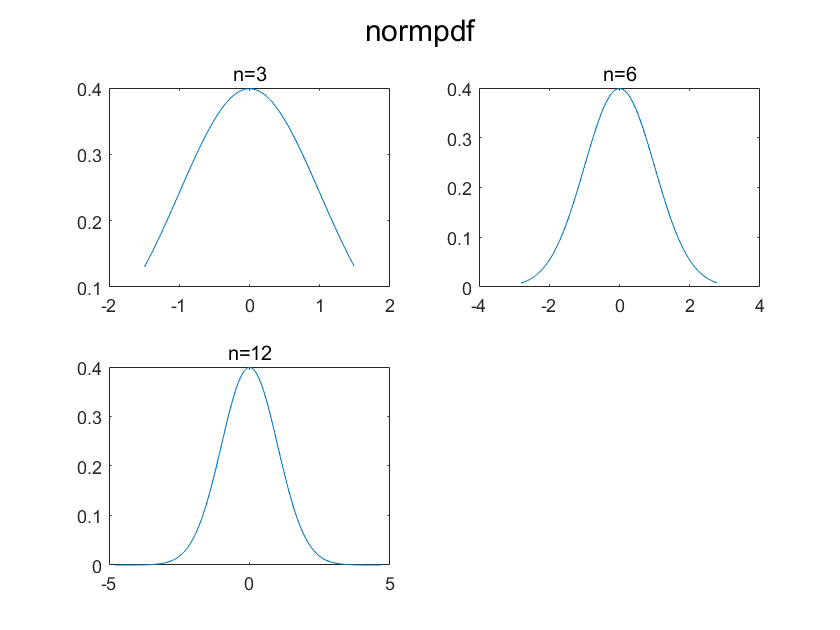

arr3 = zeros(1,10^7);
for cnt = 1:12
    for i = 1:10^7
        arr3(i) = arr3(i) + rand();
    end
end
m3 = mean(arr3);
arr3 = sort(arr3-m3);
y3 = normpdf(arr3,0,1);
subplot(2,2,3)
plot(arr3,y3)
title('n=12')

## n = 20

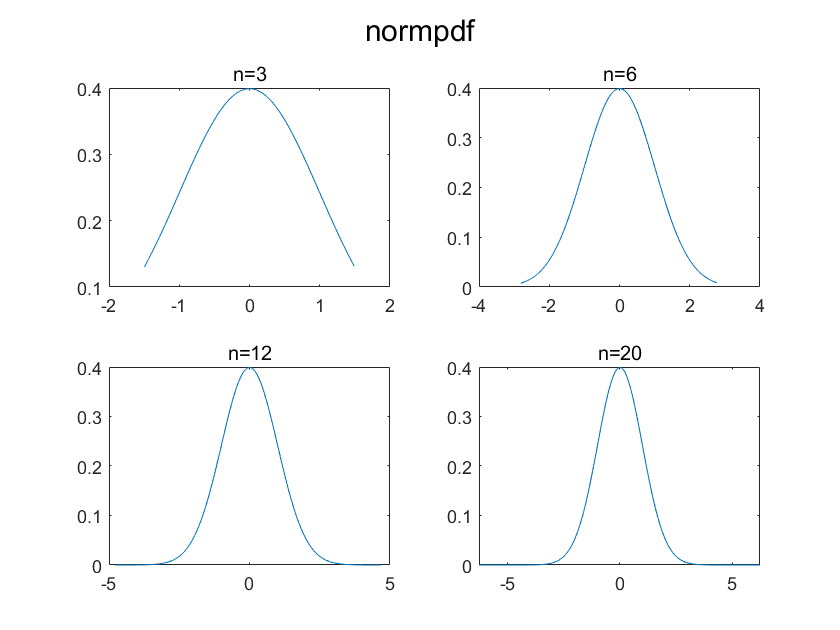

arr4 = zeros(1,10^7);
for cnt = 1:20
    for i = 1:10^7
        arr4(i) = arr4(i) + rand();
    end
end
m4 = mean(arr4);
arr4 = sort(arr4-m4);
y4 = normpdf(arr4,0,1);
subplot(2,2,4)
plot(arr4,y4)
title('n=20')